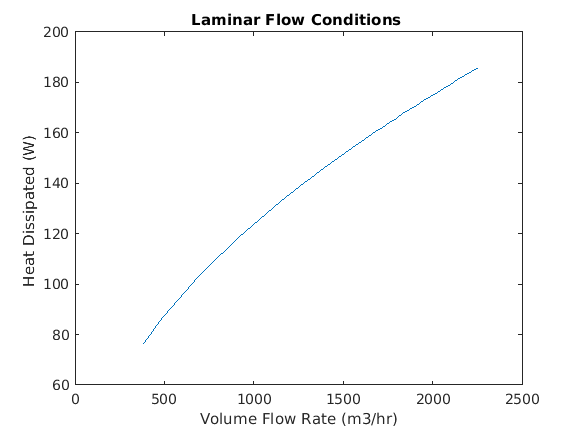

clc
clear variables
D=0.032;
L=0.08;
w=0.05;
Pr=0.709;
k=0.0258;
mu=15.36*10^(-6);
Ts=50;
Ta=25;
A=L*w;
n=25;
P1=[1:0.1:5.9];
V1=4585*P1/12;

% Laminar Flow

for i=1:50
Uinf1(i)= 4585*P1(i)/12*pi*D*D;
Re1(i)=Uinf1(i)*L/mu;
Nu1(i)=0.664*(Re1(i)^0.5)*(Pr^0.33);
h1(i)= k/L* Nu1(i);
q1(i)=2*n*h1(i)*A*(Ts-Ta);
end
plot(V1,q1)
title('Laminar Flow Conditions ')
xlabel('Volume Flow Rate (m3/hr)')
ylabel('Heat Dissipated (W) ')

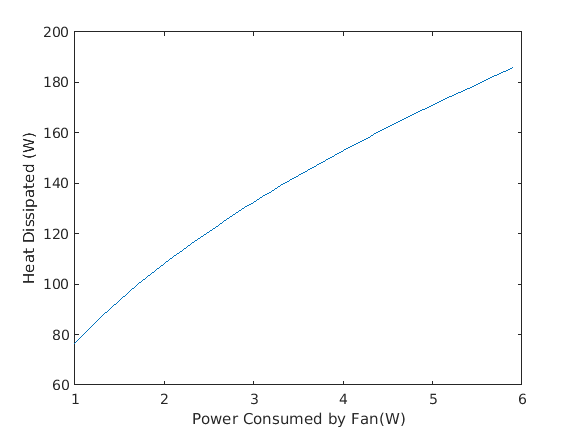

plot(P1,q1)
xlabel('Power Consumed by Fan(W)')
ylabel('Heat Dissipated (W)')

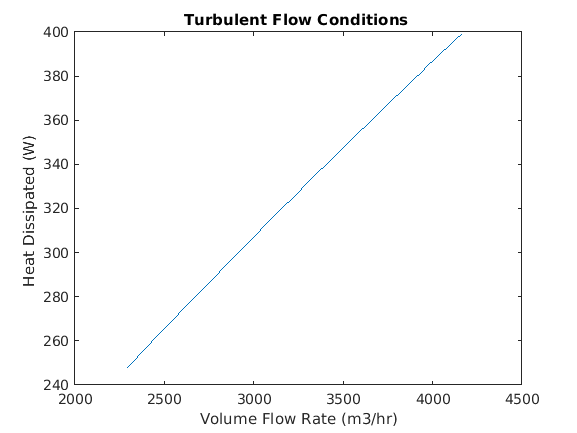


% Turbulent Flow

P2=[6:0.1:10.9];
V2=4585*P2/12;
for j=1:50
Uinf2(j)= 4585*P2(j)/12*pi*D*D;
Re2(j)=Uinf2(j)*L/mu;
Nu2(j)=0.037*(Re2(j)^0.8)*(Pr^0.33);
h2(j)= k/L* Nu2(j);
q2(j)=2*n*h2(j)*A*(Ts-Ta);
end
plot(V2,q2)
title('Turbulent Flow Conditions ')
xlabel('Volume Flow Rate (m3/hr)')
ylabel('Heat Dissipated (W) ')

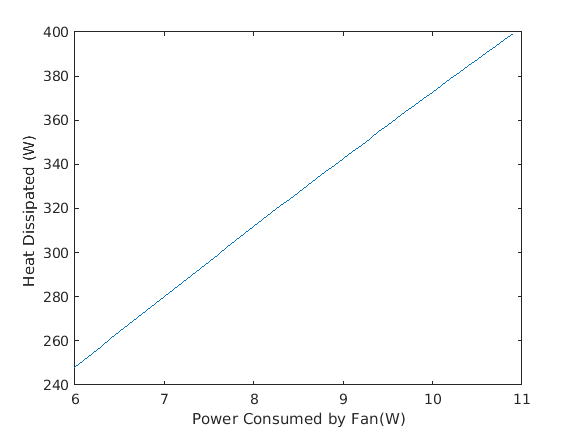

plot(P2,q2)
xlabel('Power Consumed by Fan(W)')
ylabel('Heat Dissipated (W) ')